# inputvalues

time_period = 600;
num1 = xlsread("withcolor.xlsx");
time = 1:time_period;  
T_black = 50;
T_white = 8.1;
num2 = xlsread("withoutcolor.xlsx");

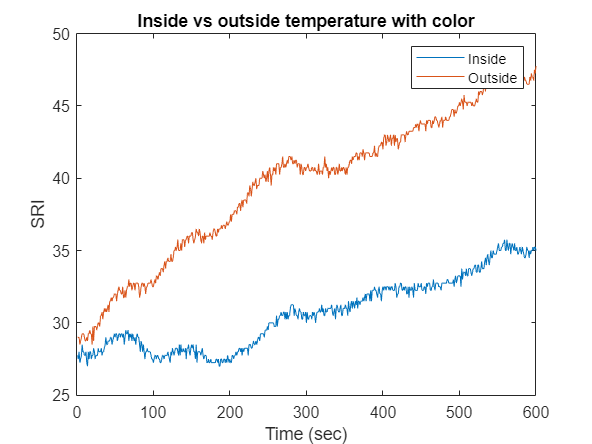


T_in1 = num1(1:time_period, 1);
T_out2 = num1(1:time_period, 3);
%T_in = round(T_in);
%T_out = round(T_out);
plot(time, T_in1)
hold on
plot(time, T_out2)
hold off
title('Inside vs outside temperature with color')
xlabel('Time (sec)')
ylabel('SRI')
legend('Inside', 'Outside')

SRI1 = (T_black-T_in1)/(T_black-T_white);
SRT11 = smooth(SRI1);


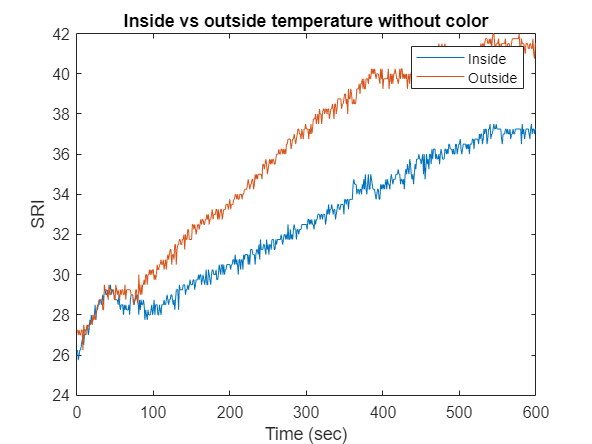

T_in2 = num2(1:time_period, 1);
T_out2 = num2(1:time_period, 3);
%T_in = round(T_in);
%T_out = round(T_out);
plot(time, T_in2)
hold on
plot(time, T_out2)
hold off
title('Inside vs outside temperature without color')
xlabel('Time (sec)')
ylabel('SRI')
legend('Inside', 'Outside')

SRI2 = (T_black-T_in2)/(T_black-T_white);
SRT12 = smooth(SRI2);


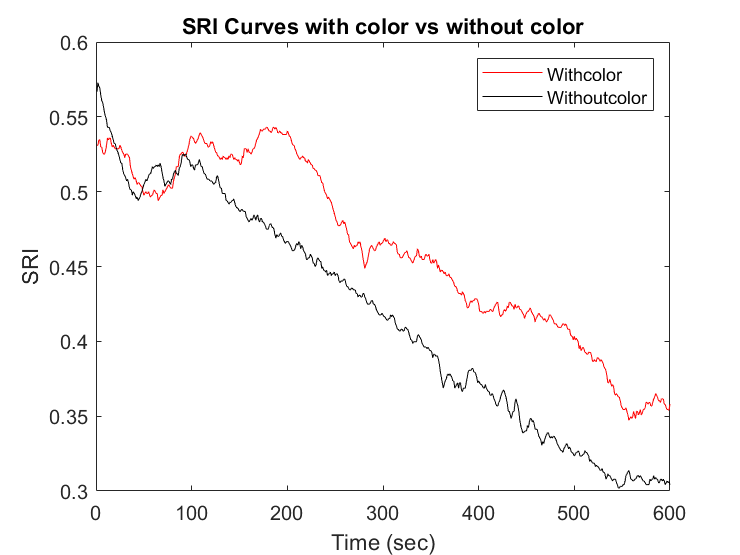

plot(time, SRT11,'r')
hold on
plot(time, SRT12,'color',[0,0,0 ])
hold off
title('SRI Curves with color vs without color')
xlabel('Time (sec)')
ylabel('SRI')
legend('Withcolor', 'Withoutcolor')

Percentage_improve = ((SRI1(600) - SRI2(600))/SRI2(600))*100;
Percentage_improve = round(Percentage_improve);
fprintf('The room cooling is improved by %d%%. ', Percentage_improve)

The room cooling is improved by 18%. 

cftool

